# Solution to *Delta-v for a Booster Rocket I *exercise

Use the rocket equation to calculate delta-v (total possible change of velocity) for a simple rocket, for a range of fuel masses. Assume that increasing fuel mass increases the height of the rocket, and therefore the mass of the rocket structure. For a fuel mass of m, the rocket equation for Δv becomes:


$$\Delta v = v_e \ln\left( 1+ \frac{m}{\alpha m + m_{fix}} \right)$$


where $v_e$ is the effective exhaust velocity, $m_{fix}$ is the fixed mass of the rocket structure (such as the engine, which doesn’t depend on the fuel mass), and $\alpha$is a dimensionless parameter that depends on the geometry of the rocket and the densities of the fuel and structure. 

## 1. Set parameters

ve = 2.6;       % exhaust velocity [km/s]
mfix = 6.1;     % fixed mass of rocket [tonnes (t)]
alpha = 0.15;   % ratio of mass of structure to mass of fuel

## 2. Create vector of fuel masses

Create a vector of masses from 100 t to 1000 t.

m = linspace(100,1000);

## 3. Calculate delta-v and plot

Calculate delta-v using the rocket equation:


$$\Delta v = v_e \ln\left( 1+ \frac{m}{\alpha m + m_{fix}} \right)$$


dv = ve*log(1 + m./(alpha*m+mfix));

Plot delta-v as a function of mass.

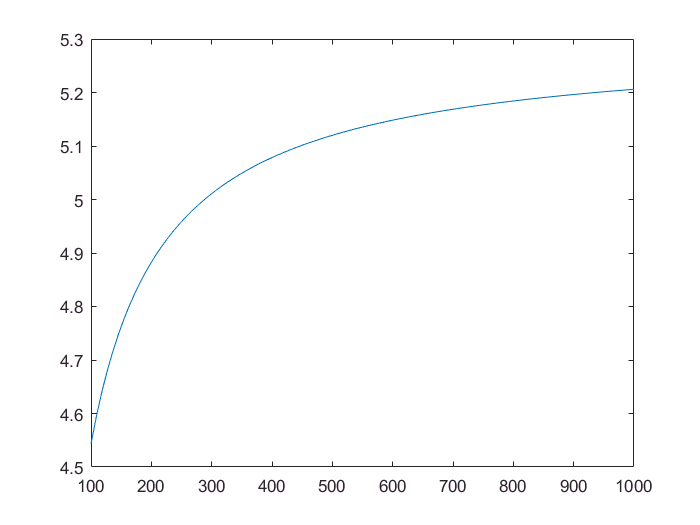

plot(m,dv)

## 4. Add annotations and grid

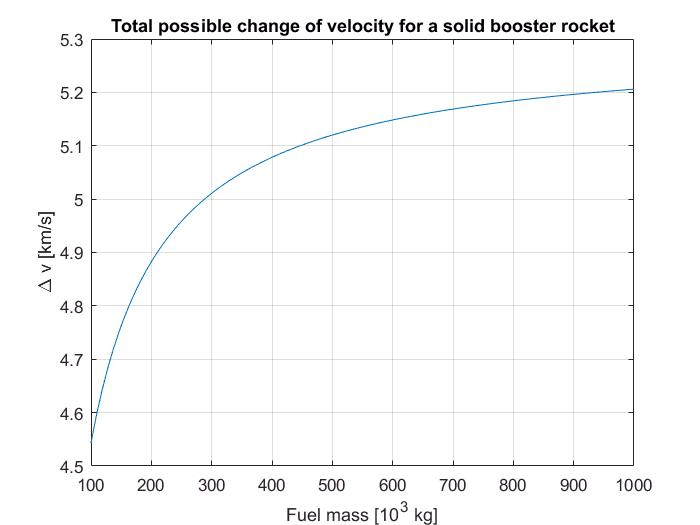

xlabel('Fuel mass [10^3 kg]')
ylabel('\Delta v [km/s]')
title('Total possible change of velocity for a solid booster rocket')
grid on